load('glass_prop.mat')
load('medium_set.mat')

%declaration of global variables
global beaker_volume beakerinnerdim beakerouterdim beakerheight mantel_A;
global top_A Tinf humidity k_glass rho_glass cp_glass epsilon_glass;


beaker_volume = glass.beaker_size(2); %m3
beakerinnerdim = glass.inner_diameter(2); %m
beakerouterdim = glass.outer_diameter(2); %m
beakerheight = glass.height(2); %m
[mantel_A, top_A] = coffeCupArea(beakerheight,beakerouterdim,beakerinnerdim);
Tinf = 20.6+273; %room temprature C 
humidity = 0.22; %room humidity
k_glass = glass.heat_conduction;
rho_glass = glass.density;
cp_glass = glass.heat_capacity;
epsilon_glass = glass.emissioncoeff;

% Initial values for temperature and mass
y0 = [(273.15+80),0.24194];

% Time interval where the ODE is solved
tint = [1 1830];

[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

current heat flux mantel -0.024 k/s
 current heat flux top -0.035 k/s 
current mass flux -0.01390 g/s
Current temp and mass 353.1 K 241.9 g 
 
current heat flux mantel -0.023 k/s
 current heat flux top -0.032 k/s 
current mass flux -0.01262 g/s
Current temp and mass 351.0 K 241.4 g 
 
current heat flux mantel -0.023 k/s
 current heat flux top -0.031 k/s 
current mass flux -0.01211 g/s
Current temp and mass 350.1 K 241.2 g 
 
current heat flux mantel -0.021 k/s
 current heat flux top -0.025 k/s 
current mass flux -0.00978 g/s
Current temp and mass 345.4 K 240.2 g 
 
current heat flux mantel -0.020 k/s
 current heat flux top -0.024 k/s 
current mass flux -0.00935 g/s
Current temp and mass 344.5 K 240.0 g 
 
current heat flux mantel -0.020 k/s
 current heat flux top -0.023 k/s 
current mass flux -0.00897 g/s
Current temp and mass 343.6 K 239.8 g 
 
current heat flux mantel -0.020 k/s
 current heat flux top -0.024 k/s 
current mass flux -0.00910 g/s
Current temp and mass 343.9 K 239.9 g 
 

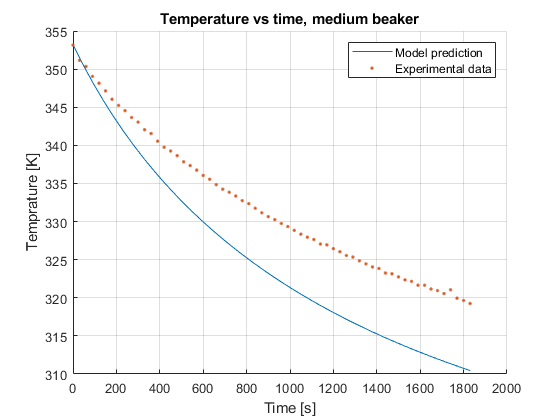

%Plotting experimental data vs modell for temperature
figure(3)
hold on
plot(t,Y(:,1))
plot(medium(2).beaker(:,1)*60,medium(2).beaker(:,2)+273.15,'.')

title('Temperature vs time, medium beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on
hold off

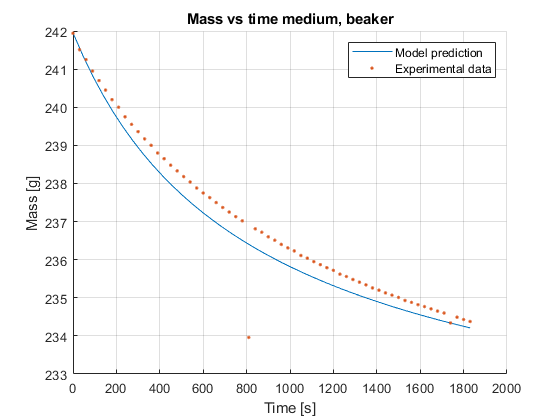

%Plotting experimental data vs modell for mass
figure(4)
hold on
plot(t,Y(:,2)*1000)
plot(medium(2).beaker(:,1)*60,medium(2).beaker(:,3),'.')

title('Mass vs time medium, beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on
hold off